unzip(fullfile('./','./','ECGData.zip'),fullfile('./','./'))
load(fullfile('./','./','ECGData.mat'))

parentDir = './';
dataDir = 'data';
helperCreateECGDirectorie(ECGData,parentDir,dataDir)

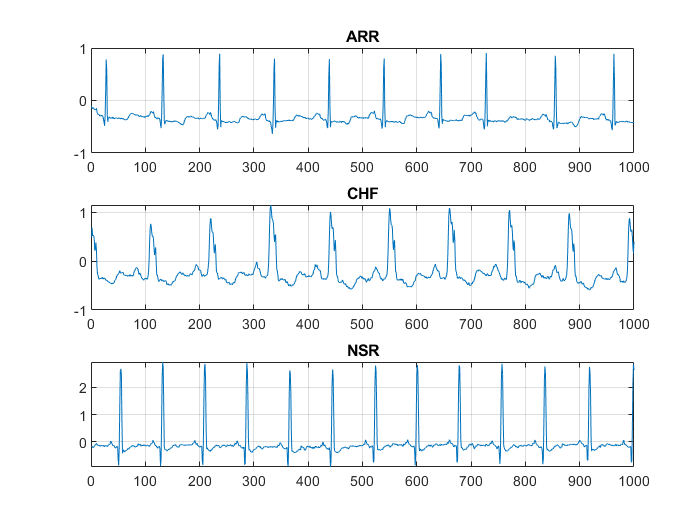

helperPlotReps(ECGData)

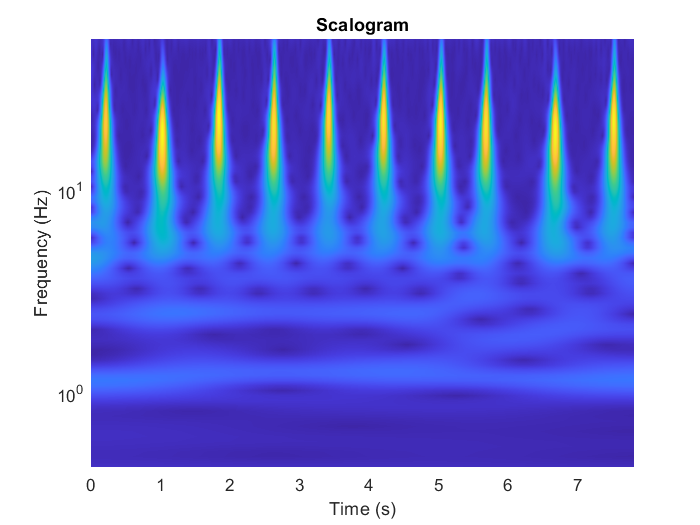

Fs = 128;
fb = cwtfilterbank('SignalLength',1000,...
    'SamplingFrequency',Fs,...
    'VoicesPerOctave',12);
sig = ECGData.Data(1,1:1000);
[cfs,frq] = wt(fb,sig);
t = (0:999)/Fs;figure;pcolor(t,frq,abs(cfs))
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)')

helperCreateRGBfromTF(ECGData,parentDir,dataDir)

allImages = imageDatastore(fullfile(parentDir,dataDir),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 130


disp(['Number of validation images: ',num2str(numel(imgsValidation.Files))]);

Number of validation images: 32


net = googlenet;

Error using googlenet (line 71)
googlenet requires the Deep Learning Toolbox Model for GoogLeNet Network support package for the pretrained weights. To install this support package, use the Add-On Explorer. To obtain the untrained layers, use googlenet('Weights','none'), which does not require the support package.

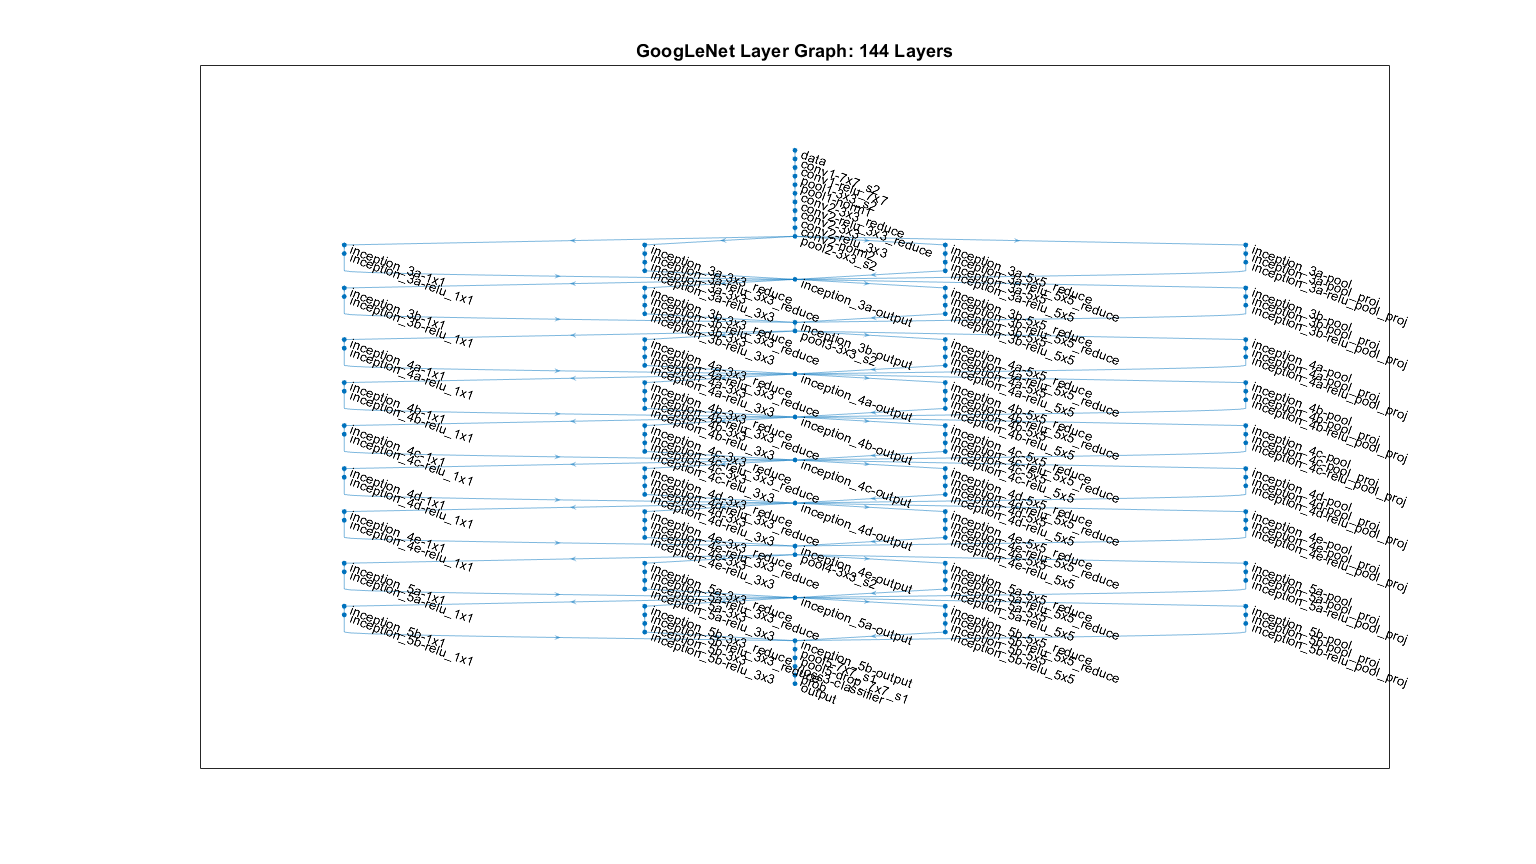

lgraph = layerGraph(net);
numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,'pool5-drop_7x7_s1',newDropoutLayer);

numClasses = numel(categories(imgsTrain.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);

lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

options = trainingOptions('sgdm',...
    'MiniBatchSize',15,...
    'MaxEpochs',20,...
    'InitialLearnRate',1e-4,...
    'ValidationData',imgsValidation,...
    'ValidationFrequency',10,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');
rng default

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:09 |       33.33% |       46.88% |       1.7424 |       1.2343 |      1.0000e-04 |
|       2 |          10 |       00:00:26 |       46.67% |       59.38% |       1.3216 |       1.0274 |      1.0000e-04 |
|       3 |          20 |       00:00:47 |       40.00% |       65.62% |       1.0886 |       0.7986 |      1.0000e-04 |
|       4 |          30 |       00:01:03 |       60.00% |       75.00% |       0.6758 |       0.5232 |      1.0000

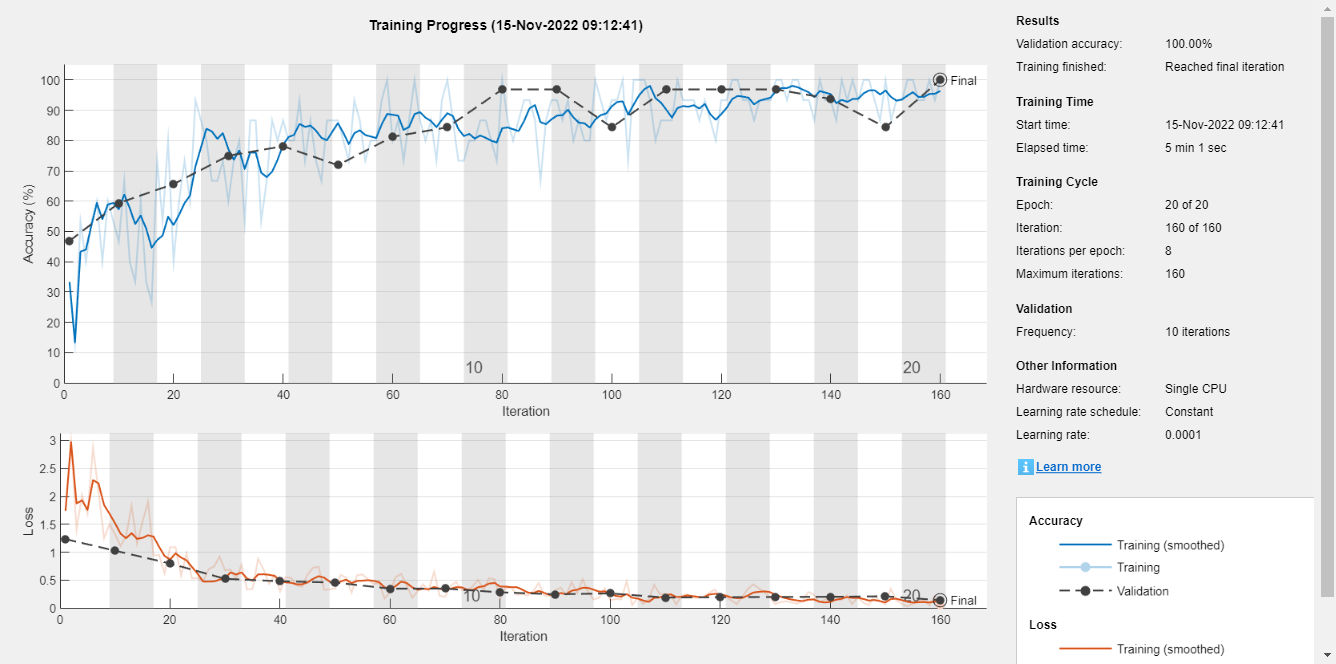

trainedGN = trainNetwork(imgsTrain,lgraph,options);

save('ecgclassification.mat',"trainedGN")

trainedGN.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


[YPred,probs] = classify(trainedGN,imgsValidation);
accuracy = mean(YPred==imgsValidation.Labels);
disp(['GoogLeNet Accuracy: ',num2str(100*accuracy),'%'])

GoogLeNet Accuracy: 100%


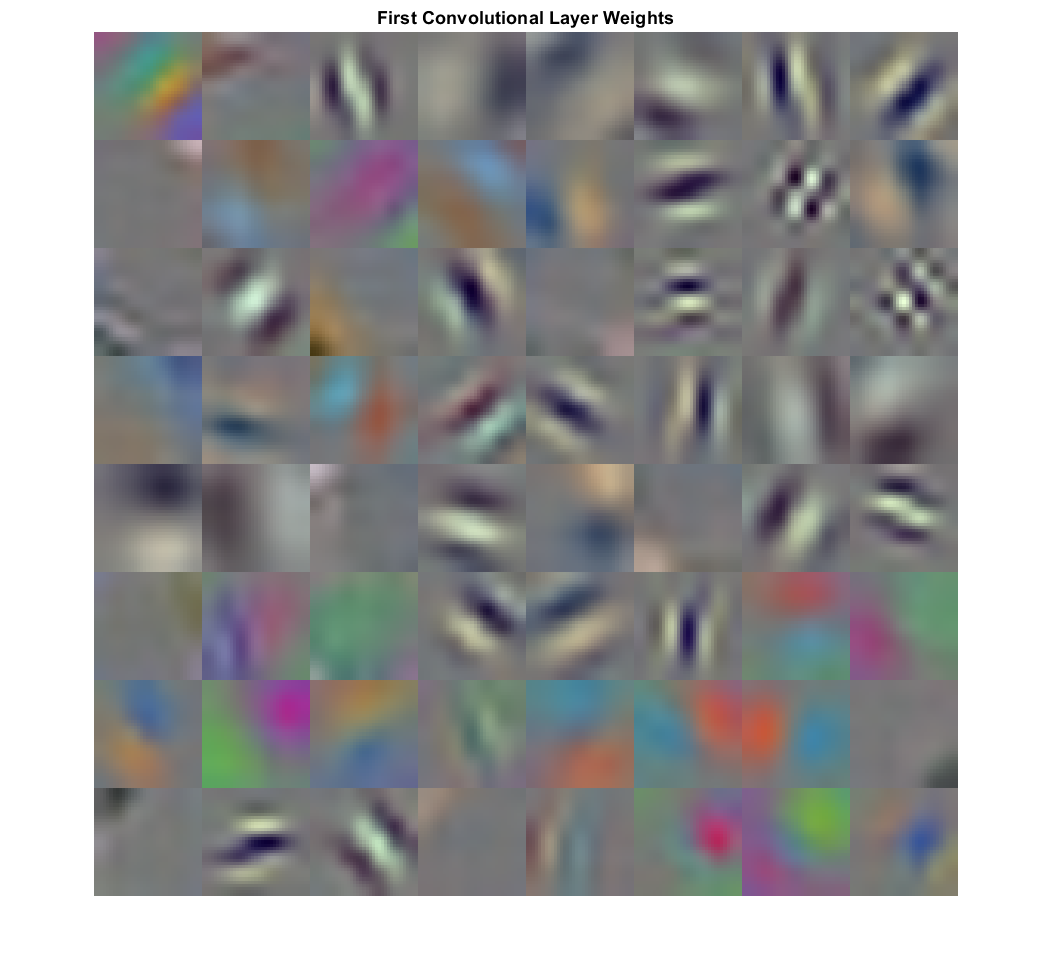

wghts = trainedGN.Layers(2).Weights;
wghts = rescale(wghts);
wghts = imresize(wghts,5);
figure
montage(wghts)
title('First Convolutional Layer Weights')

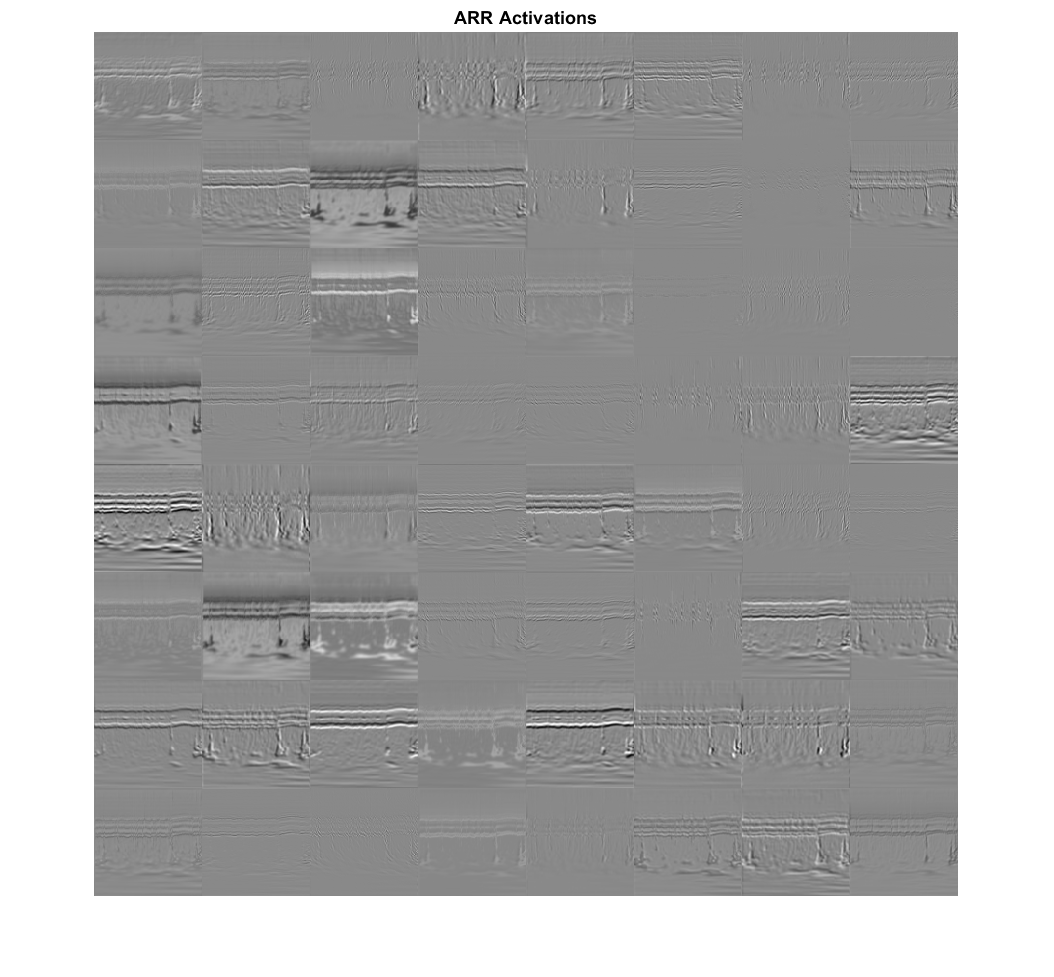

convLayer = 'conv1-7x7_s2';

imgClass = 'ARR';
imgName = 'ARR_10.jpg';
imarr = imread(fullfile(parentDir,dataDir,imgClass,imgName));

trainingFeaturesARR = activations(trainedGN,imarr,convLayer);
sz = size(trainingFeaturesARR);
trainingFeaturesARR = reshape(trainingFeaturesARR,[sz(1) sz(2) 1 sz(3)]);
figure
montage(rescale(trainingFeaturesARR),'Size',[8 8])
title([imgClass,' Activations'])

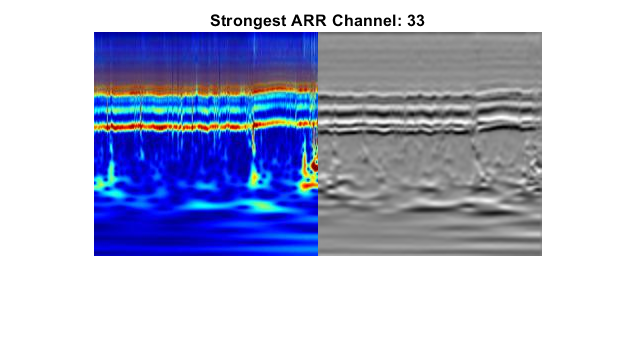

imgSize = size(imarr);
imgSize = imgSize(1:2);
[~,maxValueIndex] = max(max(max(trainingFeaturesARR)));
arrMax = trainingFeaturesARR(:,:,:,maxValueIndex);
arrMax = rescale(arrMax);
arrMax = imresize(arrMax,imgSize);
figure;
imshowpair(imarr,arrMax,'montage')
title(['Strongest ',imgClass,' Channel: ',num2str(maxValueIndex)])

sqz = squeezenet;
lgraphSqz = layerGraph(sqz);
disp(['Number of Layers: ',num2str(numel(lgraphSqz.Layers))])

Number of Layers: 68


disp(lgraphSqz.Layers(1).InputSize)

   227   227     3



lgraphSqz.Layers(end-5:end)

ans =   6×1 Layer array with layers:

     1   'drop9'                             Dropout                  50% dropout
     2   'conv10'                            Convolution              1000 1×1×512 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'                       ReLU                     ReLU
     4   'pool10'                            Global Average Pooling   Global average pooling
     5   'prob'                              Softmax                  softmax
     6   'ClassificationLayer_predictions'   Classification Output    crossentropyex with 'tench' and 999 other classes

tmpLayer = lgraphSqz.Layers(end-5);
newDropoutLayer = dropoutLayer(0.6,'Name','new_dropout');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newDropoutLayer);

numClasses = numel(categories(imgsTrain.Labels));
tmpLayer = lgraphSqz.Layers(end-4);
newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newLearnableLayer);

tmpLayer = lgraphSqz.Layers(end);
newClassLayer = classificationLayer('Name','new_classoutput');
lgraphSqz = replaceLayer(lgraphSqz,tmpLayer.Name,newClassLayer);

lgraphSqz.Layers(63:68)

ans =   6×1 Layer array with layers:

     1   'new_dropout'       Dropout                  60% dropout
     2   'new_conv'          Convolution              3 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'relu_conv10'       ReLU                     ReLU
     4   'pool10'            Global Average Pooling   Global average pooling
     5   'prob'              Softmax                  softmax
     6   'new_classoutput'   Classification Output    crossentropyex

augimgsTrain = augmentedImageDatastore([227 227],imgsTrain);
augimgsValidation = augmentedImageDatastore([227 227],imgsValidation);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       20.00% |       53.12% |       4.2032 |       1.2722 |          0.0003 |
|       1 |          13 |       00:00:11 |       60.00% |       62.50% |       0.9185 |       0.9291 |          0.0003 |
|       2 |          26 |       00:00:19 |       60.00% |       59.38% |       0.7729 |       0.8318 |          0.0003 |
|       3 |          39 |       00:00:27 |       60.00% |       62.50% |       0.7047 |       0.7393 |          0.

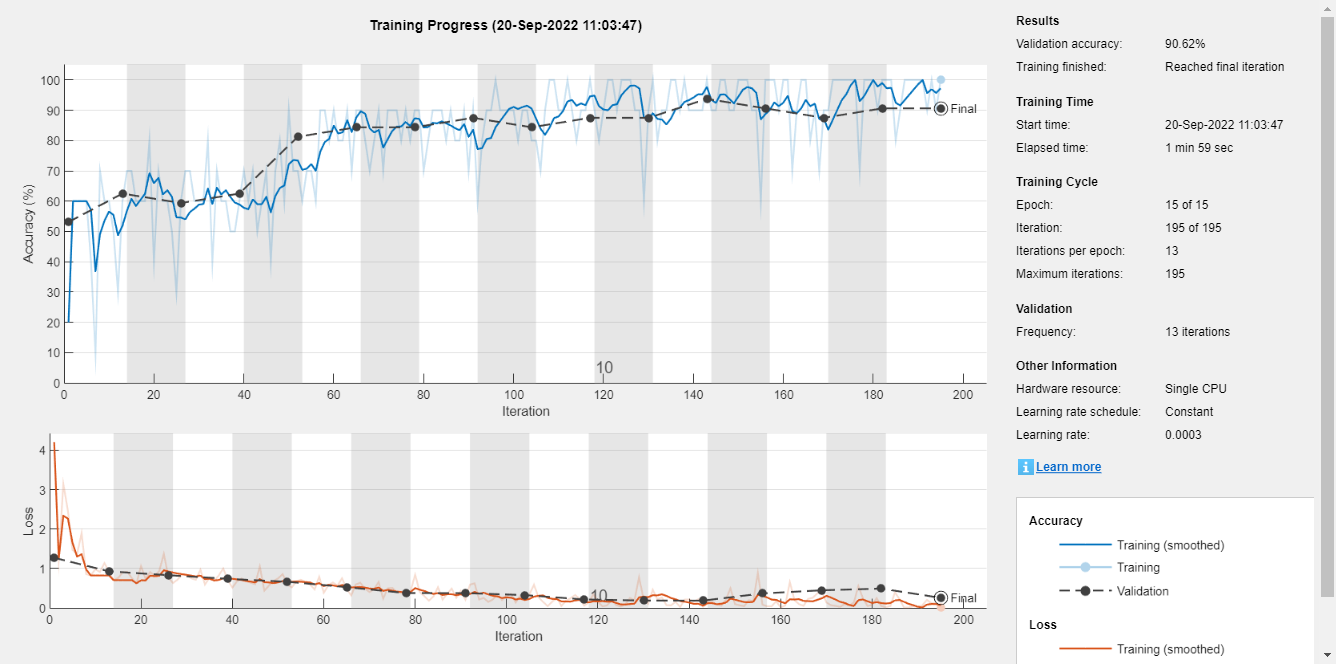

ilr = 3e-4;
miniBatchSize = 10;
maxEpochs = 15;
valFreq = floor(numel(augimgsTrain.Files)/miniBatchSize);
opts = trainingOptions('sgdm',...
    'MiniBatchSize',miniBatchSize,...
    'MaxEpochs',maxEpochs,...
    'InitialLearnRate',ilr,...
    'ValidationData',augimgsValidation,...
    'ValidationFrequency',valFreq,...
    'Verbose',1,...
    'ExecutionEnvironment','cpu',...
    'Plots','training-progress');

rng default
trainedSN = trainNetwork(augimgsTrain,lgraphSqz,opts);

trainedSN.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'new_classoutput'
         Classes: [ARR    CHF    NSR]
    ClassWeights: 'none'
      OutputSize: 3

   Hyperparameters
    LossFunction: 'crossentropyex'


[YPred,probs] = classify(trainedSN,augimgsValidation);
accuracy = mean(YPred==imgsValidation.Labels);
disp(['SqueezeNet Accuracy: ',num2str(100*accuracy),'%'])

SqueezeNet Accuracy: 90.625%


function helperCreateRGBfromTF(ECGData,parentFolder,childFolder)

imageRoot = fullfile(parentFolder,childFolder);

data = ECGData.Data;
labels = ECGData.Labels;

[~,signalLength] = size(data);

fb = cwtfilterbank('SignalLength',signalLength,'VoicesPerOctave',12);
r = size(data,1);

for ii = 1:r
    cfs = abs(fb.wt(data(ii,:)));
    im = ind2rgb(im2uint8(rescale(cfs)),jet(128));
    
    imgLoc = fullfile(imageRoot,char(labels(ii)));
    imFileName = strcat(char(labels(ii)),'_',num2str(ii),'.jpg');
    imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));
end
end
function helperPlotReps(ECGData)
folderLabels = unique(ECGData.Labels);

for k=1:3
    ecgType = folderLabels{k};
    ind = find(ismember(ECGData.Labels,ecgType));
    subplot(3,1,k)
    plot(ECGData.Data(ind(1),1:1000));
    grid on
    title(ecgType)
end
end
function helperCreateECGDirectorie(ECGData,parentFolder,dataFolder)

rootFolder = parentFolder;
localFolder = dataFolder;
mkdir(fullfile(rootFolder,localFolder))

folderLabels = unique(ECGData.Labels);
for i = 1:numel(folderLabels)
    mkdir(fullfile(rootFolder,localFolder,char(folderLabels(i))));
end
end